# Practice Linear Regression

[⇦ Linear Regression](matlab:open('./LinearRegressionSoln.mlx'))

After learning the principles of [linear regression](matlab:open('./LinearRegressionSoln.mlx')), this exercise allows you to demonstrate your understanding through practical applications in MATLAB.

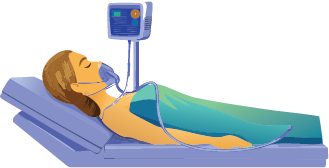

Learn and apply the linear regression workflow in MATLAB below. 

**Before you get started:**

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output Inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections, and they will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

To run the code, you can click the 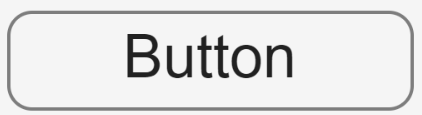**Button** provided or you can use [image: Run Section icon] **Run Section** or [image: Run and Advance icon] **Run and Advance** in the Live Editor tab of the tool strip, or the equivalent keyboard commands of Ctrl-Enter to run a section or Ctrl-Shift-Enter to run and advance.

## Example

### Load Data into a Table

We will [`load`](https://www.mathworks.com/help/releases/R2026a/matlab/ref/load.html) variables `x` and `y` from `RandomLinearData.mat` and then create a [`table` ](https://www.mathworks.com/help/releases/R2026a/matlab/ref/table.html?searchHighlight=table&s_tid=doc_srchtitle)to more easily work with our data.

  **Try**. [Load](https://www.mathworks.com/help/releases/R2026a/matlab/ref/load.html) data into a table by clicking the **button** below. 

% Load Data
load RandomLinearData.mat x y

% Create a table with x and y
 Tbl = table(x,y,VariableNames={'x','y'})
 

### Fit Linear Regression Model

We can use the [`fitlm`](https://www.mathworks.com/help/stats/fitlm.html) command in MATLAB to calculate the coefficients for a regression line. The [`fitlm`](https://www.mathworks.com/help/stats/fitlm.html) command provides us with the model formula, estimated coefficients, and model summary statistics. Here, we will focus only on the coefficients. 

  **Pro-tip**. You can remove the semicolon from your `mdl` to view these summary statistics.

  **Try**. Use the [`fitlm`](https://www.mathworks.com/help/stats/fitlm.html) function to return the regression model fit to the data stored in `Tbl`, by clicking the **button** below.

% Use the fitlm function to return the linear regression model
mdl = fitlm(Tbl); % Remove semicolon to view complete summary of statistics.
 
% Display linear model coefficients
disp("Model Coefficients:")
disp("Slope (b1): " + mdl.Coefficients.Estimate(2)) % Display b1 obtained from fitlm
disp("Intercept(b0): " + mdl.Coefficients.Estimate(1)) % Display b0 obtained from fitlm

### Plot Linear Regression Model

We can use the [plot](https://www.mathworks.com/help/releases/R2026a/matlab/ref/plot.html?searchHighlight=plot&s_tid=doc_srchtitle) function to display the scatter plot with the regression line and the 95% confidence interval. 

  **Try**.  [Plot](https://www.mathworks.com/help/matlab/ref/plot.html?s_tid=srchtitle_support_results_1_plot) the regression model by clicking the **button **below.

% Plot the linear regression model.
plot(mdl)

% Label axes
xlabel("x")
ylabel("y")
hold on % Retain plot on current axes
 

### Use Linear Regression Model to Predict One Response

We can use the [`predict`](https://www.mathworks.com/help/releases/R2026a/stats/linearmodel.predict.html) command in MATLAB to predict the response for a single x value. 

  **Pro-tip**. Run the previous section to load the data, create, and plot the linear regression model. 

  **Try**. [`Predict`](https://www.mathworks.com/help/releases/R2026a/stats/linearmodel.predict.html) the response, $y$, for $x=5.1$, and use [`scatter`](https://www.mathworks.com/help/matlab/ref/scatter.html) to plot the predicted value by clicking the **button** below. 

% Define the input value for prediction
x = 5.1; 

% Use the fitted model to predict V values for the input x
YPred = predict(mdl,x); 

scatter(x,YPred,"d","filled",DisplayName="Predicted Value")
hold off % Release all plots from current axes
 

### Use Linear Regression Model to Predict Multiple Responses

We can use the [`predict`](https://www.mathworks.com/help/releases/R2026a/stats/linearmodel.predict.html) command for a range of values by specifying a vector. 

  **Try**. We can [`predict`](https://www.mathworks.com/help/releases/R2026a/stats/linearmodel.predict.html) the responses, $y$, for $x=2.4, 3.7, 4.9, \text{and } 9.2$ and display them in a [`table`](https://www.mathworks.com/help/releases/R2026a/matlab/ref/table.html?searchHighlight=table&s_tid=doc_srchtitle) by clicking the **button** below.

% Display the prediction result
xRange = [2.4;2.7;4.9;9.2]; 

% Use the fitted model to predict V values for the range of x values
VPredRng = predict(mdl,xRange); 

% Create a table for the predicted values
PredTbl = table(xRange,VPredRng,VariableNames={'x','PredictedY'});

% Display the predicted values table
disp(PredTbl)
 

## ** Application. **Medical Ventilator Problem

A positive-pressure ventilator system delivers humidified air to a patient. Over time, water vapor from the humidifier and the patient’s exhalation condenses inside the expiratory tube. The ventilator’s monitoring system records the amount of condensed water every hour, producing the data in [`Ventilator.mat`](matlab:open('../../Data/Ventilator.mat')) with $\text{time(s)}$ in the variable, t, and $\text{Volume of Water(mL)}$ in the variable, V.

Fit a linear regression model to the data to estimate the rate of condensation (mL/s). Then, use your model to predict the amount of accumulated condensed water after 7.5 seconds.

### Load Data into a Table

 **Exercise 1. **Load the `Ventilator.mat` data into a table using the [load](https://www.mathworks.com/help/releases/R2026a/matlab/ref/load.html) and [table](https://www.mathworks.com/help/releases/R2026a/matlab/ref/table.html?searchHighlight=table&s_tid=doc_srchtitle) commands. 

% Enter code below
% Load data
load Ventilator.mat t V

% Create a table
VTbl=table(t,V,VariableNames={'t','V'});

### Fit Linear Regression Model

 **Exercise 2. **Find the linear regression model of the dependent variable, $V$, to the independent variable, $t$, and determine the model coefficients.

% Enter code below
% Use the fitlm function to return the linear regression model
Vmdl = fitlm(VTbl);
b1 = Vmdl.Coefficients.Estimate(2)
b0 = Vmdl.Coefficients.Estimate(1)

### Plot the Linear Regression Model

 **Exercise 3. **Plot the linear regression model.

  **Pro-tip**. Use [hold on](https://www.mathworks.com/help/matlab/ref/hold.html#d126e768349) to retain the plot on the axes for Exercise 5.

% Enter code below
% Plot the linear regression model.
plot(Vmdl)

% Label axes
xlabel("Time (s)")
ylabel("Volume of Water (mL)")

% Add a title
title("Condensate Accumulation in Expiratory Tube")
hold on % Retain current plot when adding new plots

### Use Linear Regression Model to Predict One Response

 **Exercise 4. **Create predicted responses to the data for $t=$7.5 seconds.

% Enter code below
tPred = 7.5;
Vpred = predict(Vmdl,tPred);
disp("At " + tPred+"s, the condensation will reach a volume of "+ Vpred + "mL.")

### Plot the Predicted Response

 **Exercise 5. **Plot the predicted response at $t=$7.5 seconds on the regression model plot.

  **Pro-tip**. Use [`hold off`](https://www.mathworks.com/help/releases/R2026a/matlab/ref/hold.html?searchPort=60962#d126e778590) to release all plots from the current axes after labeling the axes and creating a [`legend`](https://www.mathworks.com/help/releases/R2026a/matlab/ref/legend.html).

% Enter code below
scatter(tPred,Vpred,"filled","o",SeriesIndex=6) % To add the predicted data point in a new color to the existing graph
% Add a descriptive legend
legend("Data","Predictions","95% Confidence Interval","Prediction at t=7.5 seconds")
% Label axes
xlabel("time(s)")
ylabel("{Volume of water(mL)}")
hold off % Disable hold so that new plot commands clear the current axes and remove existing plots.

[⇦ Return to the Linear Regression](matlab:open('./LinearRegressionSoln.mlx'))